ROC Curves 

Neurotech

Gati Aher

dog = makedist('Normal', 'mu', 68, 'sigma', 8)

dog =   NormalDistribution

  Normal distribution
       mu = 68
    sigma =  8


other = makedist('Normal', 'mu', 52, 'sigma', 14)

other =   NormalDistribution

  Normal distribution
       mu = 52
    sigma = 14


plot

threshold accuracy

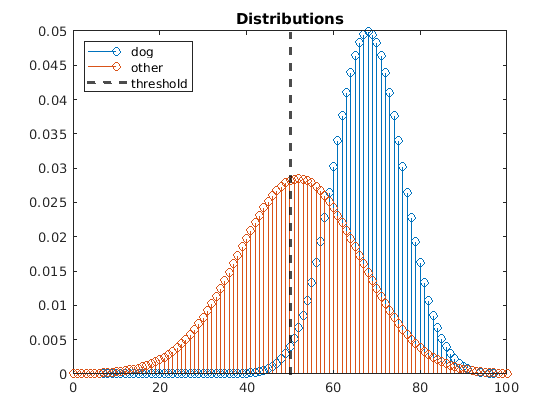

x = 0:100;
theshold = 50;
stem(x, dog.pdf(x))
hold on
stem(x, other.pdf(x))
title("Distributions")
xline(theshold, 'k--', 'LineWidth', 2)
legend( {'dog', 'other', 'threshold'}, 'Location', 'northwest')
hold off

% if FN had high cost, I would shift towards left
% so FP rate goes up, but FN rate goes down
% accuracy = (TP + TN) / (TP + TN + FP + FN)

tn = other.cdf(theshold);
fn = dog.cdf(theshold);
tp = 1 - dog.cdf(theshold);
fp = 1 - other.cdf(theshold);
accuracy = (tp + tn)/(tn + fn + tp + fp)

accuracy = 0.7155

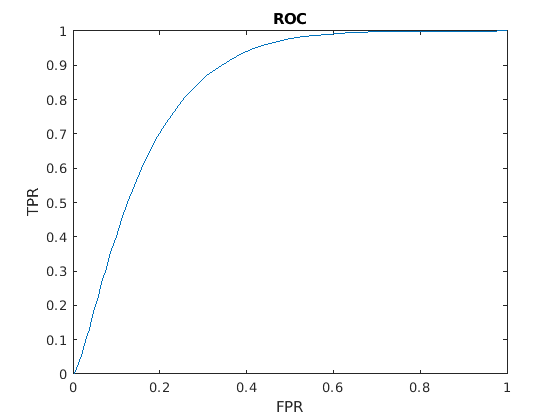


num_instances = 100;
TPR = ones(1, num_instances);
FPR = ones(1, num_instances);

for t = 1:num_instances
    tn = other.cdf(t);
    fn = dog.cdf(t);
    tp = 1 - dog.cdf(t);
    fp = 1 - other.cdf(t);
    TPR(t) = tp/(tp + fn);
    FPR(t) = fp/(tn + fp);
end

figure
plot(FPR, TPR)
hold on
title("ROC")
xlabel("FPR")
ylabel("TPR")
hold off